# Fin Flutter Analysis

clear all

## **Variables**

#### **Geometry:**

Root Chord:

Cr = 11; %inches
Crm = Cr*25.4;%mm

Tip Chord:

Ct = 2; %inches
Ctm = Ct*25.4; %mm

Semi-Span: (height from body tube to tip)

b = 3.5; %inches
bm = b*25.4; %mm

#### Material/Vehicle Properties:

Shear Modulus:

G = 2700000; %psi
Gm = G*6.8947572931e-6; %GPa

Thickness:

t = 0.125; %inches
tm = t*25.4; %mm

Elevation:

h = 0:50:30000; %ft
hm = h/3.281; %m

Ambient Temperature

T = 290; %Kelvin

## Calculations

S = 0.5*(Crm+Ctm)*bm;
lambda = Ctm/Crm;
g = 9.81; %m/s^2 
M = 0.02896; % kg/mol for air
R = 8.314; %(kg*m^2)/(s^2*K*mol)
H = 8077%(R*T)/(M*g); %m scale height

H =         8077


Cso = sqrt(1.4*T*287.7); %m/s speed of sound at sea level 
Po = .000101325; %GPa pressure at sea level 
B = bm^2/S; %aspect ratio 
NT = tm/Crm; %mm/mm normalized thickness
Vf = 1.223*Cso*exp(0.4*hm/H)*sqrt(Gm/Po)*sqrt((2+B)/1+lambda)*(NT/B)^(3/2)

Vf =        905.93       906.61        907.3       907.98       908.67       909.35       910.04       910.73       911.41        912.1       912.79       913.48       914.17       914.86       915.55       916.24       916.93       917.62       918.32       919.01        919.7        920.4       921.09       921.79       922.49       923.18       923.88       924.58       925.27       925.97       926.67       927.37       928.07       928.77       929.47       930.18       930.88       931.58       932.28       932.99       933.69        934.4        935.1       935.81       936.51       937.22       937.93       938.64       939.35       940.06


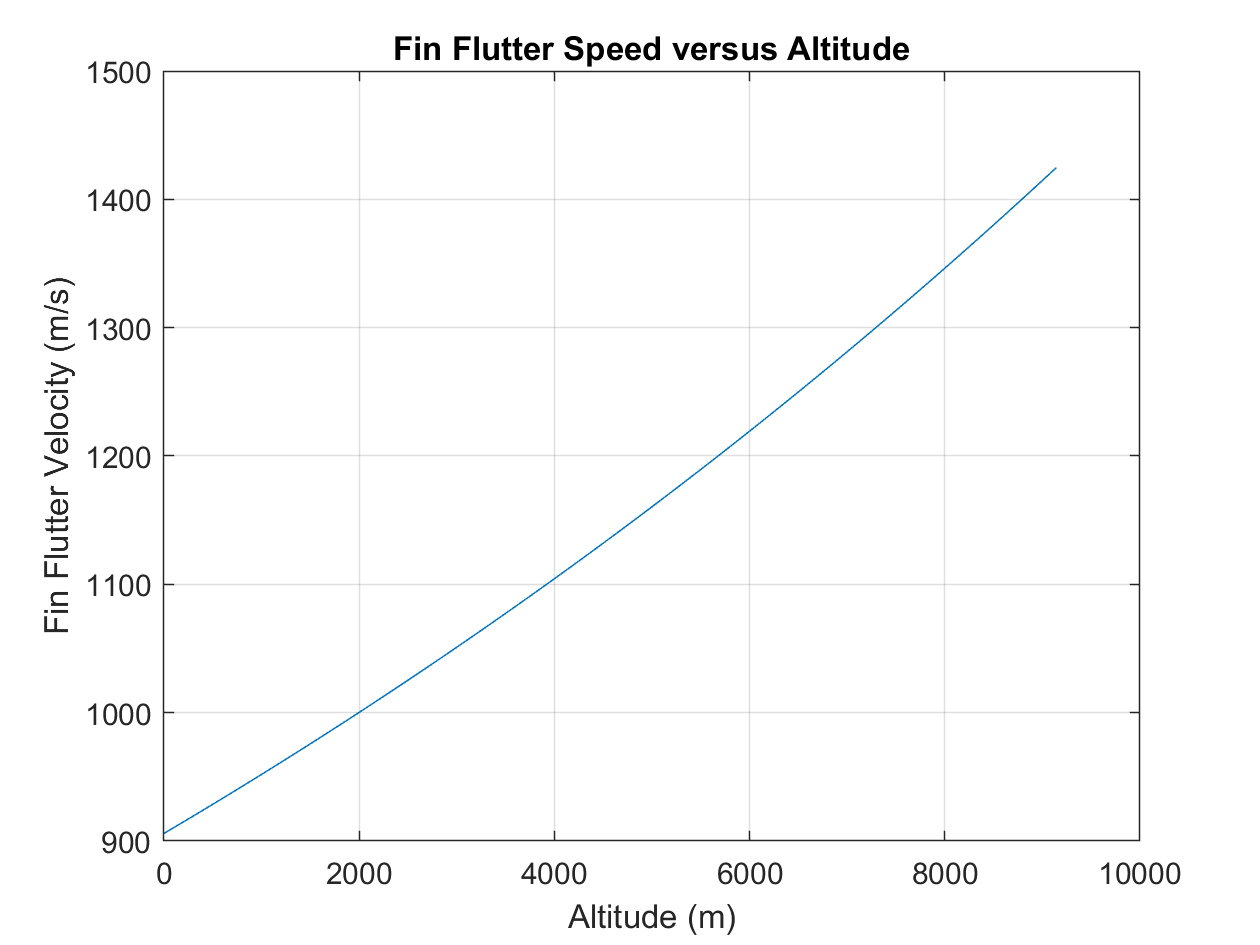

plot(hm,Vf)
ylabel 'Fin Flutter Velocity (m/s)'
xlabel 'Altitude (m)'
title 'Fin Flutter Speed versus Altitude'
grid on

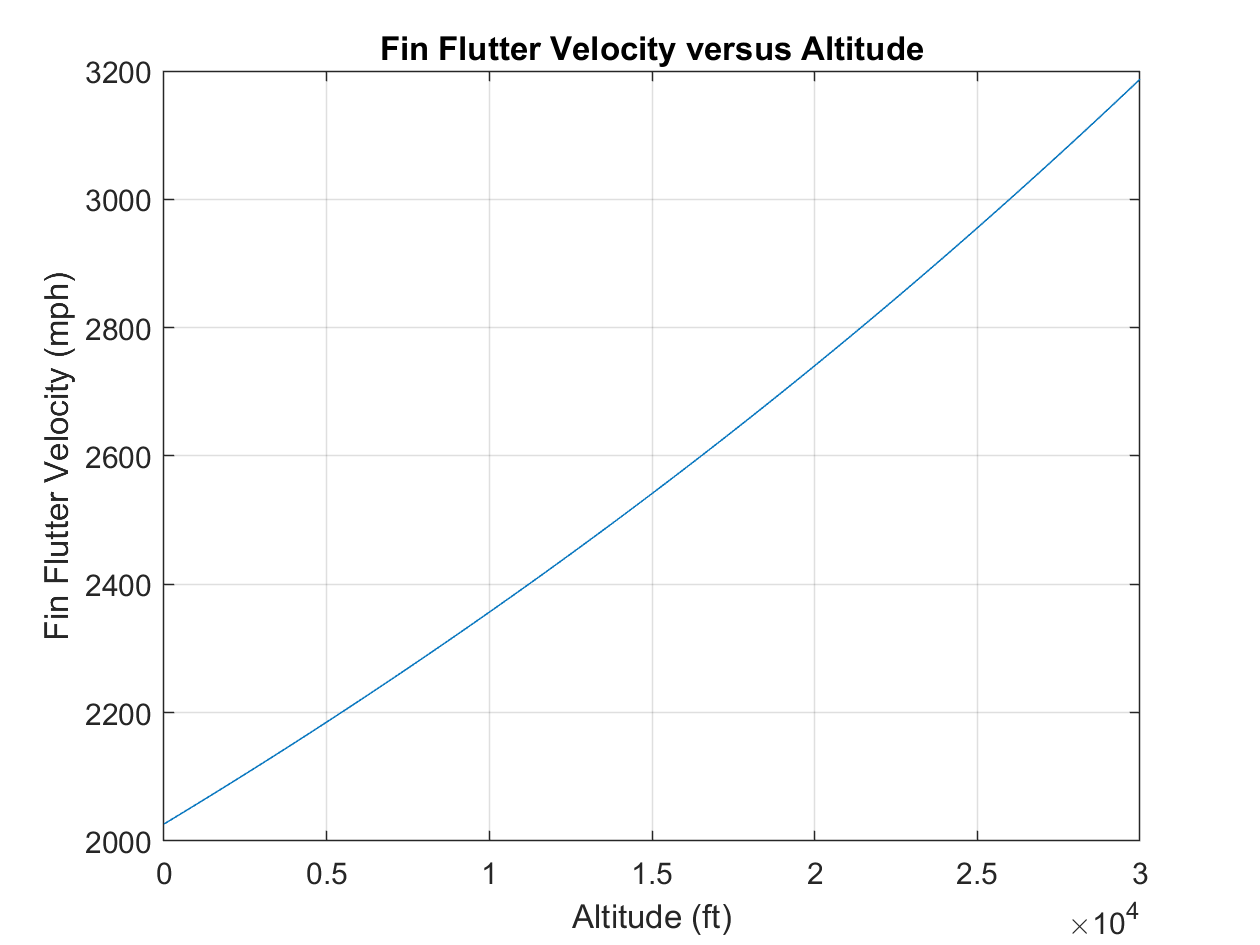

plot(hm*3.28084,Vf*2.23694)
% xlim([0 10000])
xlabel 'Altitude (ft)'
ylabel 'Fin Flutter Velocity (mph)'
grid on
title 'Fin Flutter Velocity versus Altitude'

### Find Final Fin Flutter Velocity (change h == (apogee))

height = find(h == 4650); %index of height in feet. Change number to height of max velocity, not apogee. 
Vf(height) %m/s

ans =         971.8


Vf(height)*2.23694 %mph

ans =        2173.8
